# Rendering a Scene Using a Simulated Camera

This example renders the chess set scene through a camera with a lens . The output is the spectral irradiance at the sensor surface (the optical image).

We set the focus distance and shows the depth of field for a  Double-Gauss lens.

## Initialize ISETCam and verify Docker installation

ieInit;
if ~piDockerExists, piDockerConfig; end

## Read the ChessSet Scene

thisR = piRecipeDefault('scene name','checkerboard'); %'ChessSet');

Read 1 materials and 1 textures..


thisR.set('spatial resolution',1024);

## Create a camera with a double Gaussian lens

lensname    = 'dgauss.22deg.12.5mm.json';
doubleGauss = piCameraCreate('omni','lens file',lensname);

thisR.set('camera',doubleGauss);

Set the distance that will be in focus to .8 meters

thisR.set('focus distance',0.8);

Set the camera position a little higher than default.  That makes it easier to see the ruler on the chess board.

thisR.set('from',[0,0.18,-0.5]);

Rotate the camera down a bit.  A rotation around the x-axis rotates the camera view lower.

piCameraRotate(thisR, 'x rot',-10);

It's helpful to understand the components of a recipe. Here we show a summary of the recipe information.  There is a lot for this scene.  Take your time working through it:

thisR.summarize;


File information
-----------
Input:  /home/dad/WS3/iset3d/data/scenes/checkerboard/checkerboard.pbrt
Output: /home/dad/WS3/iset3d/local/checkerboard/checkerboard.pbrt

Renderer information
-----------
Rays per pixel 32
Bounces 1

Camera parameters
-----------
Sub type: omni
Lens file name:   /home/dad/WS3/isetcam/data/lens/dgauss.22deg.12.5mm.json
Aperture diameter (mm): 5.00
Focal distance (m):	0.80
Exposure time (s):	1.000000


Field of view (deg):	

Film parameters
-----------
subtype: gbuffer
x,y resolution: 1024 1024 (samples)
diagonal:   10 (mm)

Lookat parameters
-----------
from:	0.000 0.180 -0.500
to:	0.000 -0.084 -0.039
up:	0.000 1.000 0.000
object distance: 0.531 (m)
                                       material       positions (m)          sizes (m)   
                                       _________    __________________    _______________

    000008ID_001_001_Checkerboard_O    {'board'}    {'0.00 0.00 0.00'}    {'NaN NaN NaN'}

From [0.00, 0.180000, -0.500000] to [0.00, -0.084089, -0.038853] up [0.00, 1.000000, 0.000000]
                                       material       positions (m)          sizes (m)   
                                       _________    __________________    ____

## Write and Render

We use  piWRS to Write, Render and Show the recipe.  Here we are specifying that we want to calculate only the radiance of the scene.  Notice that the rook in the rear is in good focus, but the king in the front is not.

User name: dad
Rendered time 117.21

------------------
Container command: docker --context default exec -it  pbrt-gpu-dad11245 sh -c "cd /iset/iset3d-v4/local/checkerboard && pbrt --outfile renderings/checkerboard.exr checkerboard.pbrt"
PBRT command: pbrt --outfile renderings/checkerboard.exr checkerboard.pbrt

------------------

Output file:  renderings/checkerboard.exr
*** Rendering time (checkerboard) was 117.6 sec ***



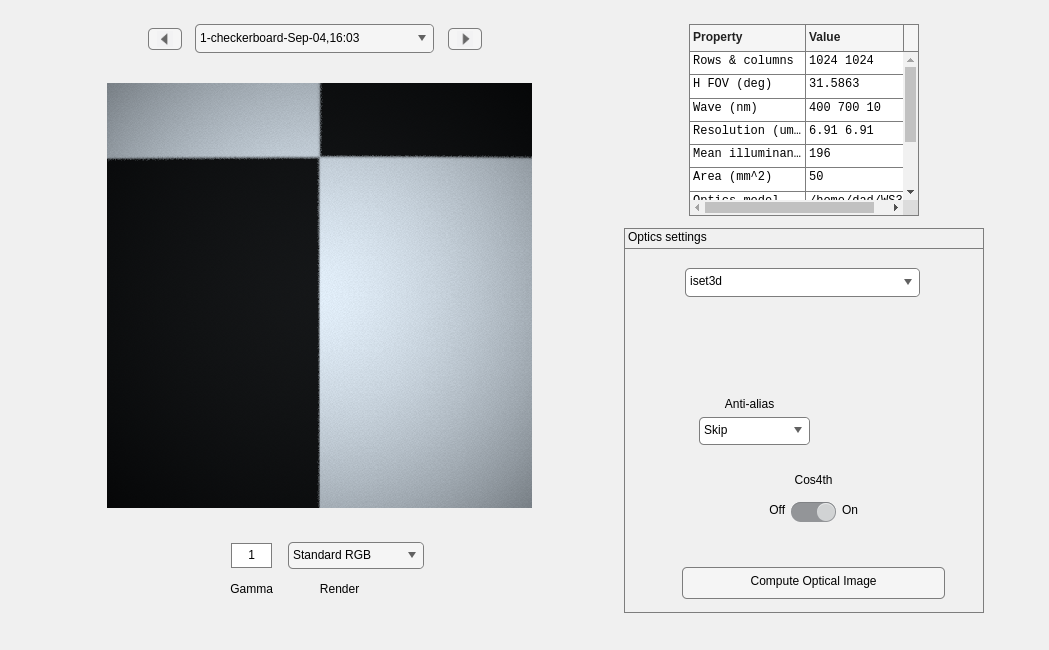

piWRS(thisR,'render type','radiance'); 

## Change the focus distance to 0.4m

This moves the in-focus plane to the king.

thisR.set('focus distance',0.4);
piWRS(thisR,'render type','radiance'); 

User name: dad
Rendered time 116.17

------------------
Container command: docker --context default exec -it  pbrt-gpu-dad11245 sh -c "cd /iset/iset3d-v4/local/checkerboard && pbrt --outfile renderings/checkerboard.exr checkerboard.pbrt"
PBRT command: pbrt --outfile renderings/checkerboard.exr checkerboard.pbrt

------------------

Output file:  renderings/checkerboard.exr
*** Rendering time (checkerboard) was 116.6 sec ***

